#### Solving for transition probability matrix $\Phi(n)$

Using the formulation in [4, Eq. (10.2.3) pp. 585]

r=1;%decimate factor
stop=5;%stop time in the units of second
stop_ind=find(time>stop,1);
t1=find(time>=circuit_time_min(4),1);
h_c4c4_dec=real(decimate(h_c4c4(t1:stop_ind+t1),r));
w_c4c4_cumul=cumtrapz(p_c4c4*h_c4c4(t1:stop_ind+t1))*sample_time;
w_c4c4_comp_cumul=1-w_c4c4_cumul(2:end);

t1=find(time>=min(min(circuit_time_min(1:3)),min(circuit_time_min(5:10))),1);
h_crcr_dec=real(decimate(h_crcr(t1:stop_ind+t1),r));
w_crcr_cumul=cumtrapz(p_crcr*real(h_crcr(t1:stop_ind+t1)))*sample_time;
w_crcr_comp_cumul=1-w_crcr_cumul(2:end);

t1=find(time>=circuit_time_min(11),1);
h_c11c11_dec=real(decimate(h_c11c11(t1:stop_ind+t1),r));
w_c11c11_cumul=cumtrapz(p_crcr*real(h_c11c11(t1:stop_ind+t1)))*sample_time;
w_c11c11_comp_cumul=1-w_c11c11_cumul(2:end);


w_crcr=p_crcr*h_crcr;
w_c11c11=p_c11c11*h_c11c11;

Evaluating ${}{^>}{w_{c_i}(t)}=\int_0^t{w_{c_i}(t)dt}$


w_c11c11_cumul=1-cumtrapz(w_c11c11)*sample_time;

w_c4c4_cumul_dec=real(decimate(w_c4c4_cumul(1:end),r));
w_crcr_cumul_dec=real(decimate(w_crcr_cumul(1:end),r));
w_c11c11_cumul_dec=real(decimate(w_c11c11_cumul(1:end),r));

N=min([length(h_c4c4_dec) length(h_crcr_dec) length(h_c11c11_dec)]);%total of points
PHI_temp=zeros(3,3);%temporal matrix to evaluate the transition probability with time
phi_11_4=zeros(1,N);

phi_c4c4=zeros(1,N);
phi_c4c4(1)=1;
phi_c4cr=zeros(1,N);
phi_c4c11=zeros(1,N);

phi_crc4=zeros(1,N);
phi_crcr=zeros(1,N);
phi_crcr(1)=1;
phi_crc11=zeros(1,N);

phi_c11c4=zeros(1,N);
phi_c11cr=zeros(1,N);
phi_c11c11=zeros(1,N);
phi_c11c11(1)=1;

for n=2:N
    %complementary CDF waiting matrix
    W_cumul=diag([w_c4c4_cumul_dec(n) w_crcr_cumul_dec(n) w_c11c11_cumul_dec(n)]);
    %account for the sum term in [1, Eq. (10.2.3) pp. 585]
    PI_H_PHI_cumul=zeros(3,3);
    for m=1:n-1
        H=diag([h_c4c4_dec(m) h_crcr_dec(m) h_c11c11_dec(m)]);
        PHI_temp=[phi_c4c4(n-m) phi_c4cr(n-m) phi_c4c11(n-m);...
                  phi_crc4(n-m) phi_crcr(n-m) phi_crc11(n-m);...
                  phi_c11c4(n-m) phi_c11cr(n-m) phi_c11c11(n-m)];
        PI_H_PHI_cumul=PI_H_PHI_cumul+PI_reduced*H*PHI_temp;
    end

    phi_c4c4(n)=PI_H_PHI_cumul(1,1)*sample_time*r+W_cumul(1,1);
    phi_c4cr(n)=PI_H_PHI_cumul(1,2)*sample_time*r;
    phi_c4c11(n)=PI_H_PHI_cumul(1,3)*sample_time*r;

    phi_crc4(n)=PI_H_PHI_cumul(2,1)*sample_time*r;
    phi_crcr(n)=PI_H_PHI_cumul(2,2)*sample_time*r+W_cumul(2,2);
    phi_crc11(n)=PI_H_PHI_cumul(2,3)*sample_time*r;    
    
    phi_c11c4(n)=PI_H_PHI_cumul(3,1)*sample_time*r;
    phi_c11cr(n)=PI_H_PHI_cumul(3,2)*sample_time*r;
    phi_c11c11(n)=PI_H_PHI_cumul(3,3)*sample_time*r+W_cumul(3,3);

end


% %including the delay when entering into the circuit
% phi_c4c4=horzcat(zeros(1,ceil(circuit_time_min(4)/sample_time/r)),phi_c4c4);
% phi_c4cr=horzcat(zeros(1,ceil(circuit_time_min(4)/sample_time/r)),phi_c4cr);
% phi_c4c11=horzcat(zeros(1,ceil(circuit_time_min(4)/sample_time/r)),phi_c4c11);


phi_c11c4=horzcat(zeros(1,ceil(circuit_time_min(4)/sample_time/r)),phi_c11c4);
phi_c11c11=horzcat(zeros(1,ceil(circuit_time_min(11)/sample_time/r)),phi_c11c11);

phi_c11c11=horzcat(zeros(1,ceil(circuit_time_min(11)/sample_time/r)),phi_c11c11);
phi_crcr=horzcat(zeros(1,ceil(circuit_time_min(5)/sample_time/r)),phi_crcr);
figure;
%phi_c11c4
n_end=min([length(phi_c4c4),length(phi_c11c4),length(phi_crcr)]);
plot((0:n_end-1)*sample_time*r,phi_c4c4(1:n_end),'LineWidth',2); hold on; grid on;
plot((0:n_end-1)*sample_time*r,phi_crcr(1:n_end),'LineWidth',2); hold on; grid on;
plot((0:n_end-1)*sample_time*r,phi_c11c11(1:n_end),'LineWidth',2); hold on; grid on;
ylabel('$\phi_{c_{11}c_4}(\tau)$','Interpreter','latex');

annotation('arrow',[0 0.1],[0 0.1]);
t_n=find(phi_c4c4>10^(-7),1)

t_n = 1

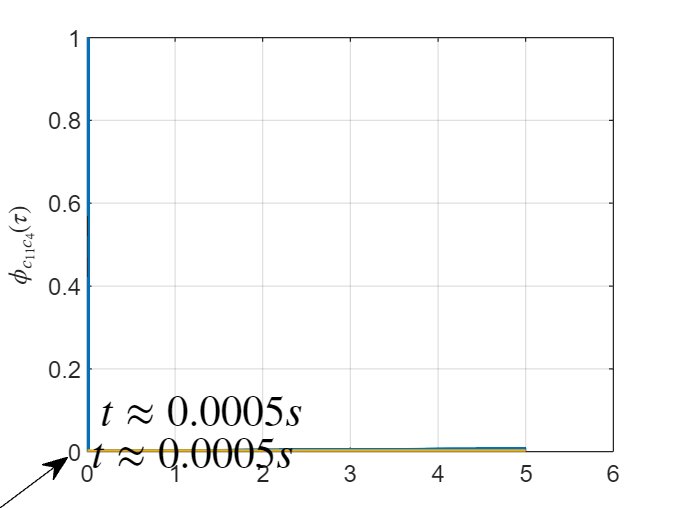

text([0 0.1],[0 0.1],strcat('$t\approx',num2str(t_n*r*sample_time),' s$'),'FontSize',fontsize,'Interpreter','latex');